Cd0=0.02       %0.014-0.020

Cd0 = 0.0200

AR=3            %Assumed 

AR = 3

e=1.78*(1-0.045*AR^0.68)-0.64

e = 0.9709

k=1/(pi*AR*e)   

k = 0.1093

Clmax=2.5       %Assumed: 1.2-1.6

Clmax = 2.5000

mu=0.02

mu = 0.0200

Cd_0LG=0.009    %0.006-0.012

Cd_0LG = 0.0090

Cd_0HLDto=0.005 %0.003-0.008

Cd_0HLDto = 0.0050

Cl_c=0.4        %0.3-0.5

Cl_c = 0.4000

Cl_flapTo=0.5   %0.3-0.8

Cl_flapTo = 0.5000


Vs=30%change it

Vs = 30

Vmax=120        %1.2 Vcruise- Vcruise was assumed to be 140m/s

Vmax = 120

V_r=25

V_r = 25

ROC=7           %3-10

ROC = 7

ROC_ceiling=2.5

ROC_ceiling = 2.5000

LbyD_max=15     %Assumed

LbyD_max = 15

W_To=300*9.81

W_To = 2943

Sto=500

Sto = 500


n=150

n = 150

row=1.225

row = 1.2250

ceiling=11000

ceiling = 11000

g0=9.81

g0 = 9.8100

g=9.81

g = 9.8100

sigma=(1-6.873*10^(-6)*ceiling)^4.26

sigma = 0.7154

%stall speed
WbyS_Vs=0.5*row*(Vs^2)*Clmax*ones(1,100)

WbyS_Vs = 	1.0e+03 *

    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781    1.3781


TbyW_Vs=linspace(0,5,100);

%Vmax 
WbyS_Vmax=linspace(60,1500,n);
TbyW_Vmax= 2*k*WbyS_Vmax/(row*sigma*Vmax^2) +(row*sigma*(Vmax^2)*Cd0*0.5)./WbyS_Vmax 

TbyW_Vmax =     2.1044    1.8127    1.5922    1.4196    1.2809    1.1669    1.0716    0.9908    0.9214    0.8612    0.8084    0.7617    0.7202    0.6830    0.6496    0.6193    0.5917    0.5665    0.5435    0.5222    0.5026    0.4845    0.4676    0.4520    0.4373    0.4236    0.4108    0.3988    0.3874    0.3768    0.3667    0.3572    0.3482    0.3396    0.3315    0.3238    0.3164    0.3094    0.3028    0.2964    0.2903    0.2845    0.2789    0.2736    0.2685    0.2636    0.2589    0.2543    0.2500    0.2458


%ROC 
WbyS_roc=linspace(60,1500,n);
TbyW_roc=(ROC/sqrt(2/(sigma*row*sqrt(Cd0/k))))./(WbyS_roc.^(0.5))+1/LbyD_max

TbyW_roc =     0.4579    0.4298    0.4069    0.3879    0.3718    0.3579    0.3457    0.3349    0.3253    0.3167    0.3088    0.3017    0.2951    0.2891    0.2835    0.2784    0.2735    0.2690    0.2648    0.2608    0.2571    0.2536    0.2502    0.2471    0.2440    0.2412    0.2384    0.2358    0.2334    0.2310    0.2287    0.2265    0.2244    0.2224    0.2204    0.2185    0.2167    0.2150    0.2133    0.2117    0.2101    0.2086    0.2071    0.2056    0.2043    0.2029    0.2016    0.2003    0.1991    0.1979


%take off distance
WbyS_Sto=linspace(60,1500,n)

WbyS_Sto = 	1.0e+03 *

    0.0600    0.0697    0.0793    0.0890    0.0987    0.1083    0.1180    0.1277    0.1373    0.1470    0.1566    0.1663    0.1760    0.1856    0.1953    0.2050    0.2146    0.2243    0.2340    0.2436    0.2533    0.2630    0.2726    0.2823    0.2919    0.3016    0.3113    0.3209    0.3306    0.3403    0.3499    0.3596    0.3693    0.3789    0.3886    0.3983    0.4079    0.4176    0.4272    0.4369    0.4466    0.4562    0.4659    0.4756    0.4852    0.4949    0.5046    0.5142    0.5239    0.5336


Cl_To=Cl_c+Cl_flapTo

Cl_To = 0.9000

Cd_0To=Cd0+Cd_0LG+Cd_0HLDto

Cd_0To = 0.0340

Cd_To=Cd_0To+k*Cl_To^2

Cd_To = 0.1225

Cl_r=2*WbyS_Sto/(row*V_r^2)

Cl_r =     0.1567    0.1820    0.2072    0.2325    0.2577    0.2830    0.3082    0.3335    0.3587    0.3839    0.4092    0.4344    0.4597    0.4849    0.5102    0.5354    0.5607    0.5859    0.6112    0.6364    0.6617    0.6869    0.7121    0.7374    0.7626    0.7879    0.8131    0.8384    0.8636    0.8889    0.9141    0.9394    0.9646    0.9898    1.0151    1.0403    1.0656    1.0908    1.1161    1.1413    1.1666    1.1918    1.2171    1.2423    1.2676    1.2928    1.3180    1.3433    1.3685    1.3938


Cd_G=Cd_To-mu*Cl_To

Cd_G = 0.1045

TbyW_Sto=(mu-(mu+Cd_G./Cl_r).*exp(0.6*row*sigma*g*Cd_G*Sto./WbyS_Sto))./(1-exp(0.6*row*sigma*g*Cd_G*Sto./WbyS_Sto))

TbyW_Sto =     0.6944    0.6066    0.5418    0.4924    0.4538    0.4228    0.3975    0.3766    0.3590    0.3440    0.3311    0.3199    0.3101    0.3014    0.2937    0.2868    0.2806    0.2751    0.2700    0.2654    0.2612    0.2573    0.2537    0.2504    0.2473    0.2445    0.2419    0.2394    0.2371    0.2349    0.2329    0.2309    0.2291    0.2274    0.2258    0.2243    0.2228    0.2214    0.2201    0.2189    0.2177    0.2166    0.2155    0.2144    0.2134    0.2125    0.2116    0.2107    0.2099    0.2091


%ceiling
WbyS_ceiling=linspace(60,1500,n);
TbyW_ceiling=ROC_ceiling./(sigma*sqrt(WbyS_ceiling*2/(row*sigma*sqrt(Cd0/k))))

TbyW_ceiling =     0.1953    0.1813    0.1699    0.1604    0.1523    0.1454    0.1393    0.1339    0.1291    0.1248    0.1209    0.1173    0.1141    0.1110    0.1083    0.1057    0.1033    0.1010    0.0989    0.0969    0.0951    0.0933    0.0916    0.0901    0.0885    0.0871    0.0858    0.0845    0.0832    0.0820    0.0809    0.0798    0.0787    0.0777    0.0768    0.0758    0.0749    0.0740    0.0732    0.0724    0.0716    0.0708    0.0701    0.0694    0.0687    0.0680    0.0674    0.0667    0.0661    0.0655


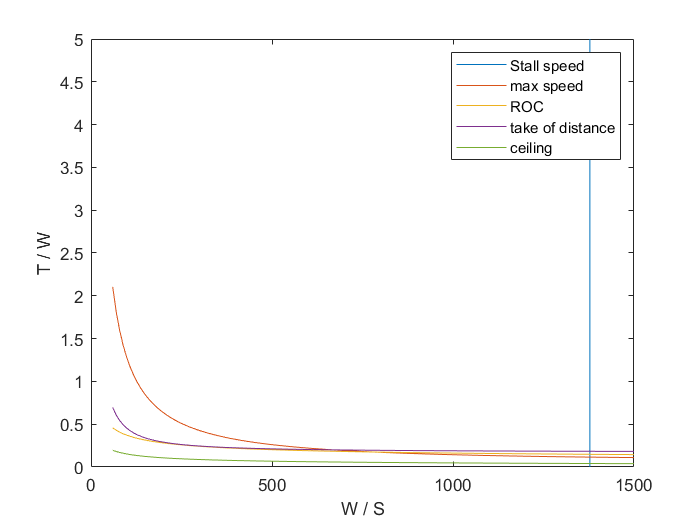

plot(WbyS_Vs,TbyW_Vs)
hold on
plot(WbyS_Vmax,TbyW_Vmax)
plot(WbyS_roc,TbyW_roc)
plot(WbyS_Sto,TbyW_Sto)
plot(WbyS_ceiling,TbyW_ceiling)
xlabel("W / S")
ylabel("T / W")
legend("Stall speed","max speed","ROC","take of distance","ceiling")
hold off